Changes made and functions implemented:

- KL.m created. Implements the KL-divergence objective function for pdco.

- PDCO_KL.m created. Given inputs A, b, mu, lmda, and delta, runs the pdco algorithm in pdco.m for the KL.m objective function. 

- Modified lines 509, 1111, and 1366 in pdco.m to allow pdObj to take two inputs.

- Commented out lines 370-373 and 1376-1378 in pdco.m to avoid interruptions to the algorithm's execution 

- Commented out print statement on line 513 of pdco.m

 Matt, Oct 10th additional changes:

- Piggyback PDCO print statemtent to create a tracing array. (lines 306, 1198)

- modified PDCO output to return fill trace iteration

print = 0;

## Testing PDCO on data

We test PDCO_KL.m on 2 datasets

- rho-meson_testproblem.mat

- synthetic-UEG_testproblem.mat

### Synthetic UEG

data = load('data/synthetic-UEG_testproblem.mat');
A = data.A;
[m, n] = size(A);

b = data.b_avg;
b = b';
x0 = data.x; % already normalized
x0 = x0'; 
mu = data.mu; % prior provided
mu = double(mu'); % was single precision

% code to find the best lmda by comparing |x-x0|/sqrt(n)

lmdas = logspace(-15, -2, 100);
delta = 10e-4;

min_rmse = inf;
best_lmda = NaN;

for i = 1:length(lmdas)
    lmda = lmdas(i);
    x = PDCO_KL(A, b, mu, lmda, delta, print);
    rmse = norm(x0 - x)/sqrt(n);
    if rmse < min_rmse
        min_rmse = rmse;
        best_lmda = lmda;
    end
end

% it seems that the best lmda is the smallest one tested
fprintf('Best: lmbda = (%f) | RMSE: = %f\n', best_lmda, min_rmse); 

Best: lmbda = (0.000000) | RMSE: = 0.005658


#### RMSE, Residual, and visualization

lmda_test = 10e-2;
[x, y, z, inform,tracer] = PDCO_KL(A, b, mu, lmda_test, delta, print);

xsum = sum(x);
disp('Synthetic UEG');

Synthetic UEG


disp('Sum of entries of x:')

Sum of entries of x:


disp(xsum); 

    1.0000



disp('Res:')

Res:


disp(norm(A*x - b));

    0.0719



disp('RMSE:')

RMSE:


disp(norm(x - x0)/sqrt(n));

    0.0119



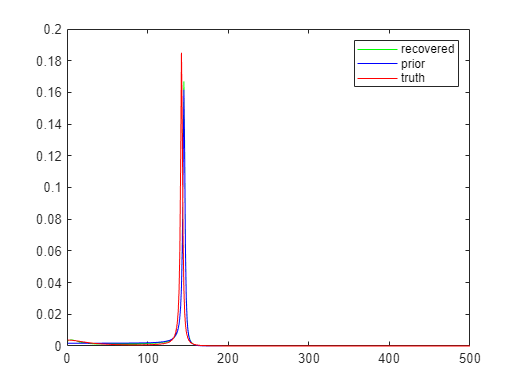


x_ = 1:n;
figure
plot(x_ ,x,'g-',x_, mu,'b', x_, x0,'r')
legend('recovered', 'prior', 'truth')

### Rho-meson

disp('Rho-meson');

Rho-meson


data = load('data/rho-meson_testproblem.mat'); % the same as PhysicsData?
A = data.A;
b = data.b_avg;
x0 = data.x;
mu = data.mu; % prior provided

Note: Rho-meson appears to be the same as PhysicsData.